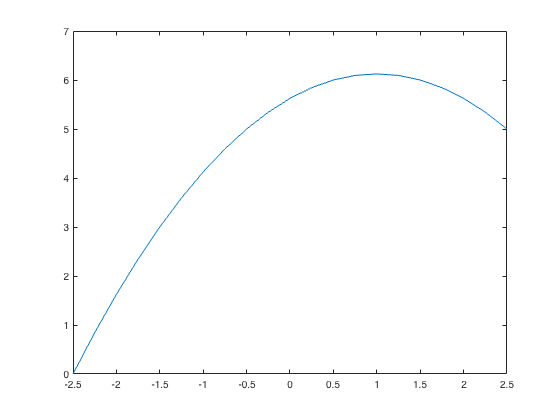

nr = 2;
Regioni = [-2.5, 0, 1, 1;0, 2.5, 1, 1];
divReg = [10, 10];
CodCCR = [2, 0;0, 1];
ValCCR = [0, 0; 0, -2.5];

problema = 1;

[ npD, ndivD, puntipD, CodCC, ValCC, ElementiD, PropElD ] = DiscretizzaDominio( nr, Regioni, divReg, CodCCR, ValCCR);
[ K_glob, t_glob ] = AssemblaSistema( npD, ndivD, ElementiD, PropElD, CodCC, ValCC, puntipD, problema);

phi=K_glob\t_glob;

plot(puntipD,phi)

%%